# IMU Noise Analysis

Program to analyse the PSD of IMU 

## Import Raw Data

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\ICM20689 Data"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\IMUOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

%Loop over every folder 
for folderCount = 1 : numel(folders)
    

    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", folderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.


## Create Text file with full dataset


outFileName = fullfile(outdir_2, "IMU_Data.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");



## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["TimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

%Read in table
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";
wavefile = fullfile(outdir_2, "IMU_Data.txt");
WaveTable = readtable(wavefile, opts);


## Calculate Power Spectrum

Fs = 105

Fs = 105

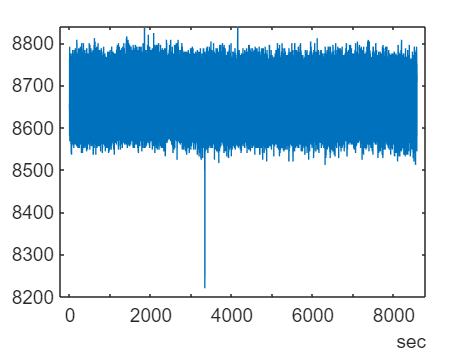


WaveTimeTable = table2timetable(WaveTable, "SampleRate", Fs);


plot(WaveTimeTable.Time, WaveTimeTable.Heave);



% Scale 
Heave = ( WaveTimeTable.Heave ) / 4096 * 9.81;
%Detrend 
Heave = detrend(Heave);

Heave = highpass(Heave, 0.03, Fs)

Heave =    -0.0378
    0.0101
    0.0484
    0.0484
    0.0580
   -0.0857
    0.0197
   -0.0378
    0.0197
   -0.0282


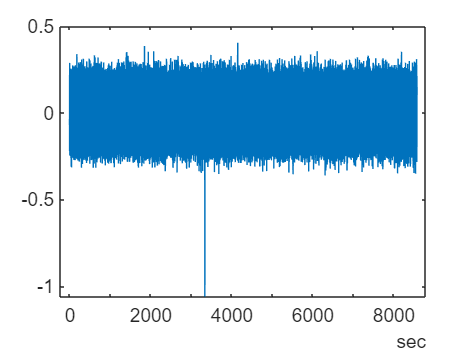


plot(WaveTimeTable.Time, Heave);


[pspectrumHeave, f] = pspectrum(Heave, Fs);


dispSpectrumHeave = pspectrumHeave.*(2*pi*f).^(-4);
 
clf

## Plot Noise PSD

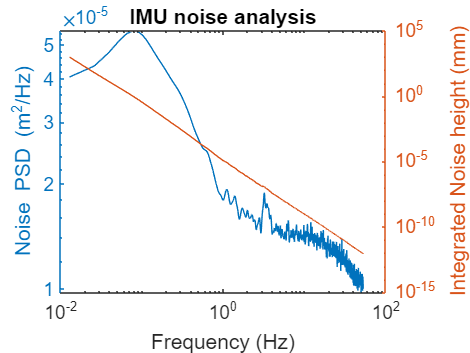

yyaxis left;
loglog(f,pspectrumHeave);
ylabel("Noise PSD (m^2/Hz)");
xlabel("Frequency (Hz)");
yyaxis right
loglog(f,dispSpectrumHeave*1000);
ylabel("Integrated Noise height (mm)");
title("IMU noise analysis")

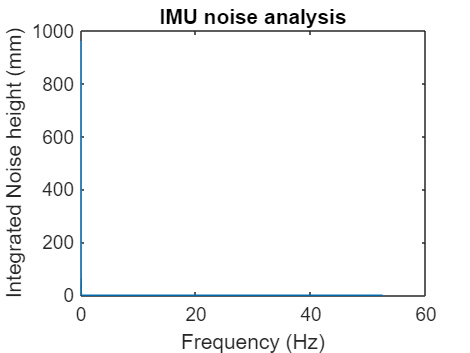


clf

plot(f,dispSpectrumHeave*1000);
ylabel("Integrated Noise height (mm)");
xlabel("Frequency (Hz)");
title("IMU noise analysis")